# Kalman Filter for Rocket

A Kalman filter is a useful tool for combining both measurements and modeling into a single refined state estimate technique. Running a Kalman filter on the rocket could be useful for more accurately detecting apogee as well as getting a better idea of how high the rocket goes.

The first thing to do is to make some fake sensor data. This was done by solving a second order equation of motion of an object. Note that this model considers air resistance. The output of this model is displayed below.

%run simple model to generate fake positoin data for rocket
dt = 0.1;
[T, D] = altitude_model(dt);  %dt

For the filter we will first only consider the z position since this can be measured with a barometer chip. We will also use the vertical acceleration which can be measured with an accelerometer(?). To make the fake sensor data, we will add some normally distributed noise with a standard deviation of 10.

The fake sensor data is plotted below.

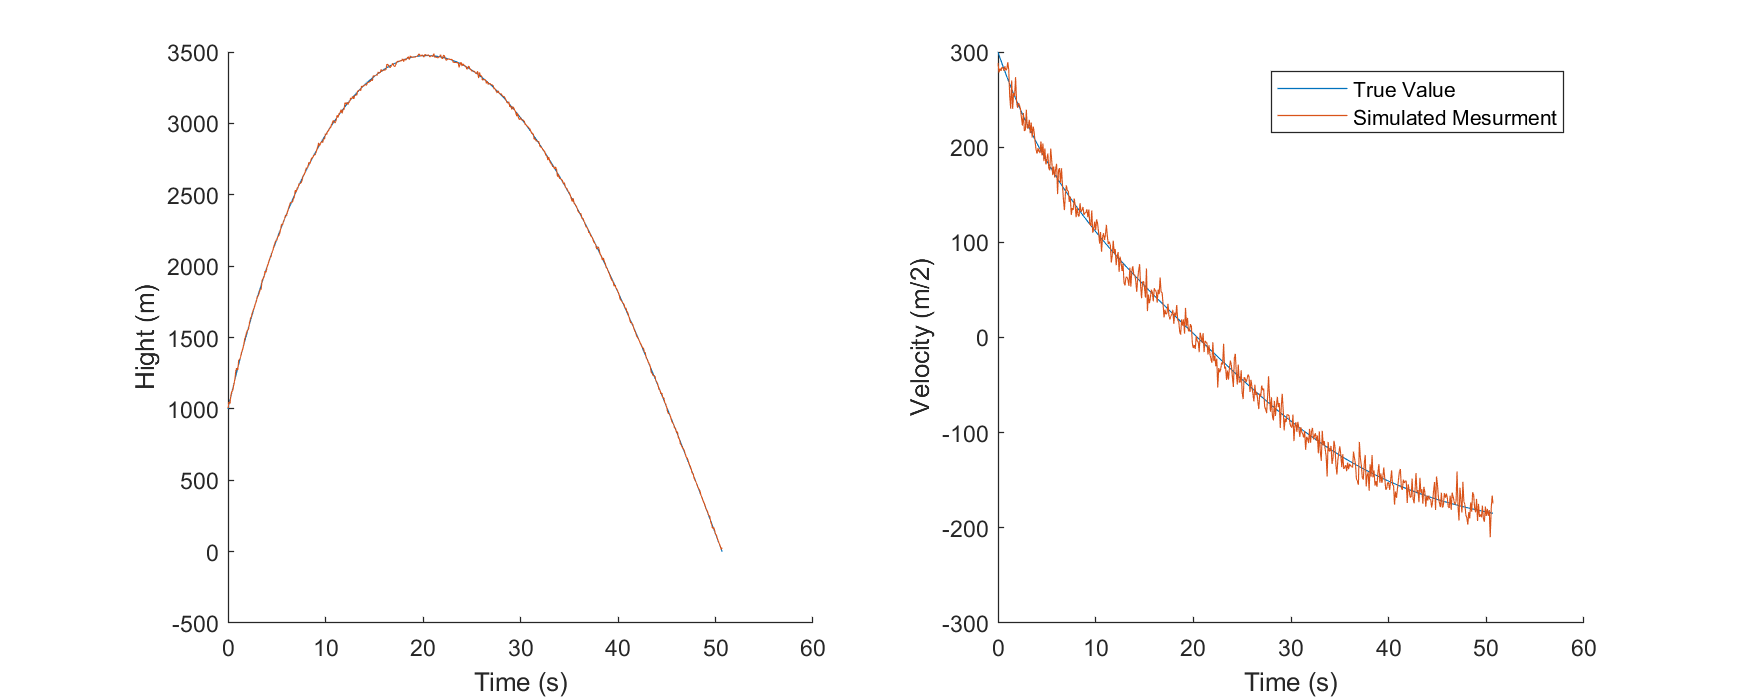

true_state = [D(:,3), D(:,6)]; %extract z position and velocity data
%create normal distributed noise
sigma = 10;
noise = sigma*randn(size(true_state));
%add noise to data
noise_state = true_state + noise;

%plotting
figure(1)
clf
set(figure(1), "Position", [0 0 1000, 400])
subplot(1,2,1)
hold on
plot(T, true_state(:,1))
plot(T, noise_state(:,1))
hold off
xlabel("Time (s)")
ylabel("Hight (m)")


subplot(1,2,2)
hold on
plot(T, true_state(:,2))
plot(T, noise_state(:,2))
hold off
xlabel("Time (s)")
ylabel("Velocity (m/2)")
legend("True Value", "Simulated Mesurment")

The algorithm works by feeding the filter function the current “best-guess” at what the state of the system is (`state:` a vector containing vertical position and velocity). We also feed in our “best guess” for what the prediction covariance matrix (`p_cov`) of the state is. Essentially, we are making a guess and then guessing at how good our first guess is…

Finally, we feed the Kalman filter a new measurement of the state. In this case, this is just the next elements in the fake sensor data.

The `kalman_update` function takes all this information, does some fancy linear algebra (which we can talk about latter), and spits out a new state/”best-guess” as well as a new covariance matrix for that state.

We can keep calling the function for as many sensor data points as we have. We should also write the state after each iteration to a matrix so we can plot it latter.

%define some global matricies
global R Q MU;
R = [sigma^2 0 ; 0 sigma^2];  %measurement noise covarience (from the sensor: in this case sigam^2)

Error using sigma (line 82)
Not enough input arguments.

Q = [25 0 ; 0 25]; %proccess noise covarience (from perturbations like aerodynamic drag)
%increasing Q will make filter follow measurmements more
%decrasing will make it follow internal model more
%tune this value to minmize the error

MU = -9.8;

dt = 0.1;

%set inital state and proccess covariance to first measurement
state = noise_state(1,:)';
p_cov = Q;

%make some empty arrays
kalman_state = zeros(size(noise_state));
kalman_state(1,:) = noise_state(1,:);

%loop through all mesurments and run filter
for i=2:length(noise_state)
    measurement = noise_state(i,:)';
    [state, p_cov] = kalman_update(state, p_cov, measurement, dt);
    kalman_state(i,:) = state';
end

%plot results
plot_res(T, true_state, noise_state, kalman_state)

In the above example, we see that the Kalman filter is abount twice as accurate as using the sensor data alone. We can tune the filter by adjusting the R matrix. This is the process covariance noise, and it encodes how much uncertainty there is in the built-in model that runs inside the Kalman filter. Because this model does not consider the air resistance, we are effectively using R to tell the kalman filter to not get to comfortable trusting only the simple model.

You can see that changing the value of R make the Kalman filter move between following the sensor data and following the internal model (not shown) more closely.

test_data = csvread('dtl1.csv', 1);

%define some global matricies
global R Q MU;
R = [1000 0 ; 0 1000];  %measurement noise covarience (from the sensor: in this case sigam^2)
Q = [25 0 ; 0 25]; %proccess noise covarience (from perturbations like aerodynamic drag)
%increasing Q will make filter follow measurmements more
%decrasing will make it follow internal model more
%tune this value to minmize the error

MU = -9.8;
drag_term = false;
t_max = 300;
t_start = 1;


%set inital state and proccess covariance to first measurement
state = [test_data(t_start,2) ; test_data(t_start,3)];
p_cov = Q;

%make some empty arrays
kalman_state = zeros(t_max-t_start,2);
kalman_state(1,:) = state';



%loop through all mesurments and run filter
for i=t_start+1:t_max
    dt = test_data(i,1) - test_data(i-1,1);
    measurement = [test_data(i,2) ; test_data(i,3)];
    
    [state, p_cov] = kalman_update(state, p_cov, measurement, dt, drag_term);

    if state(2) < 0 && ~drag_term
        test_data(i,1)
        drag_term = true
    end
    kalman_state(i-t_start+1,:) = state';
end

ans = 12.3000

drag_term = logical
   1

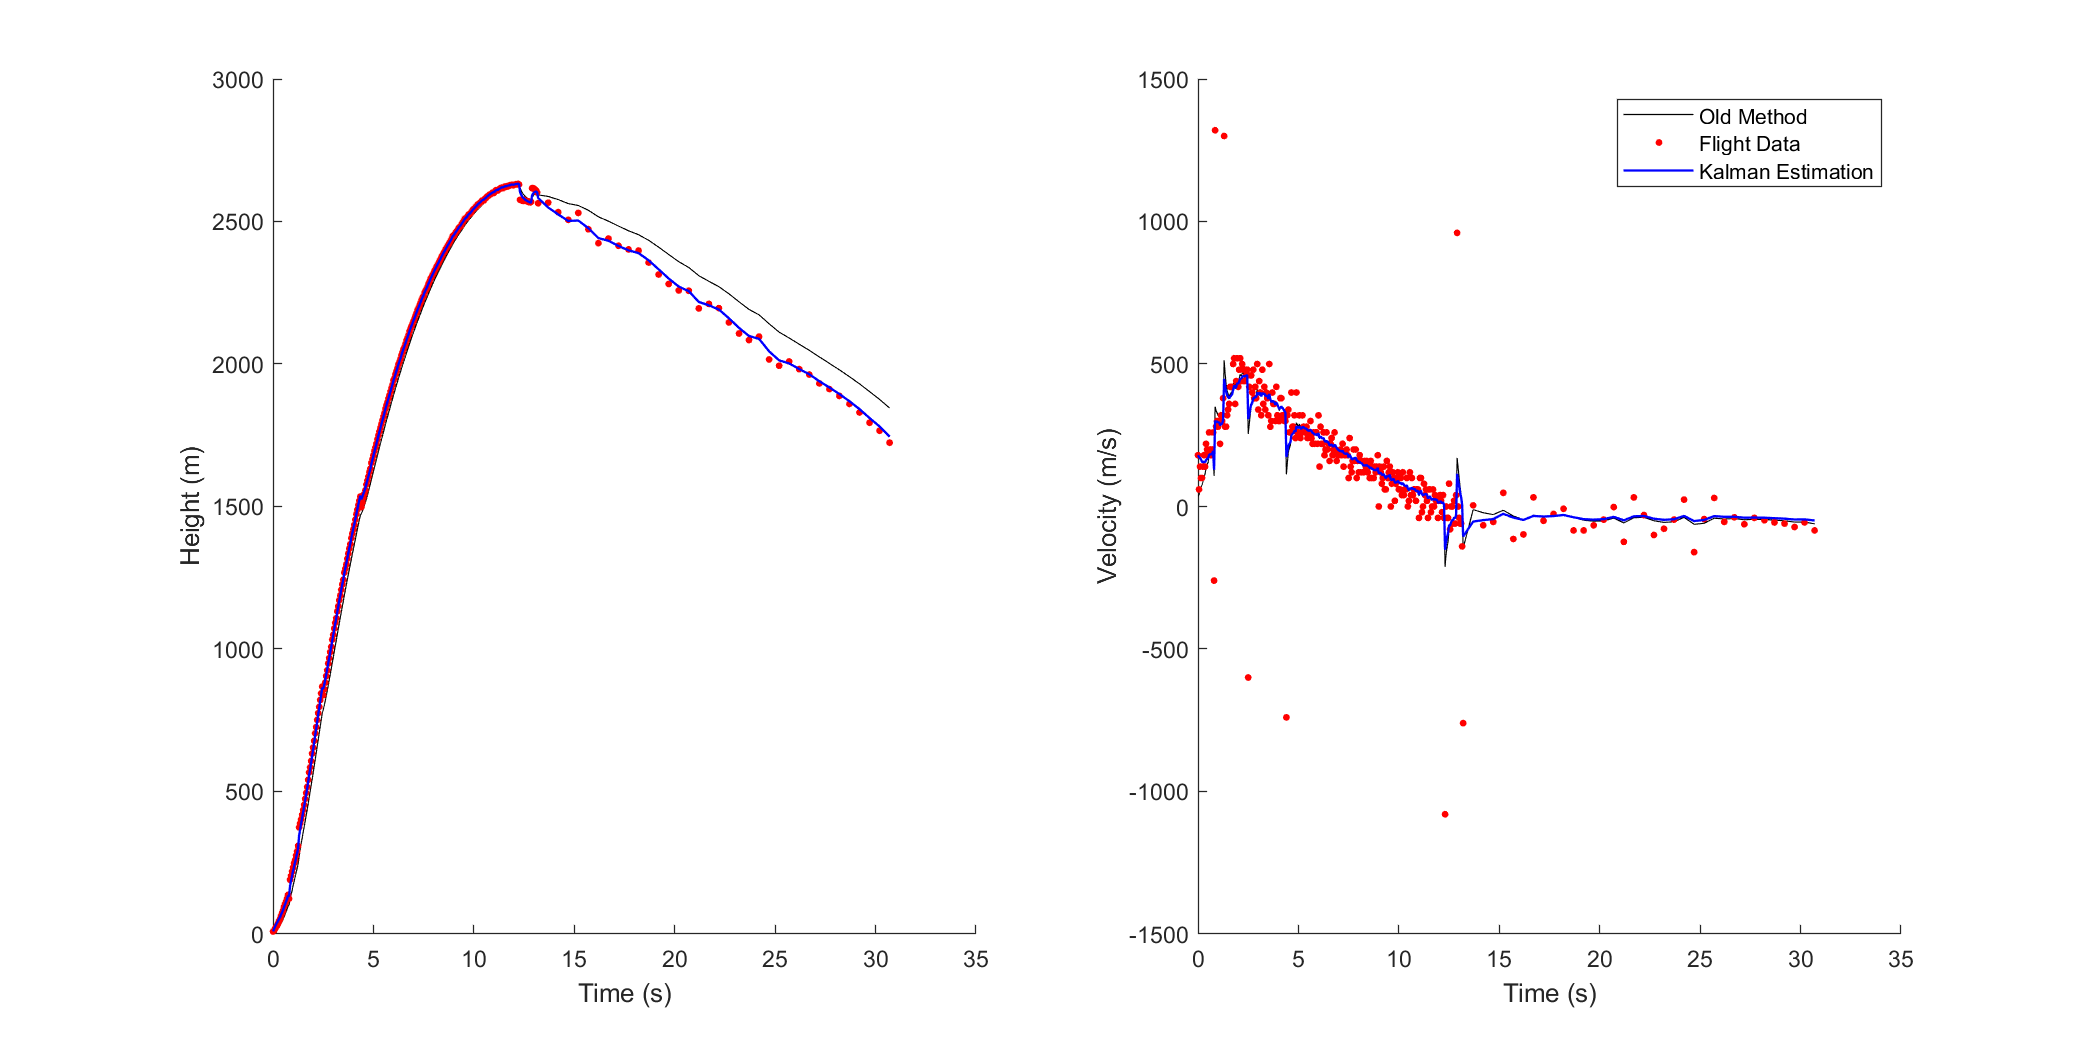


plot_res2(test_data(t_start:t_max,1), test_data(t_start:t_max,2:3), test_data(t_start:t_max,4:5), kalman_state)

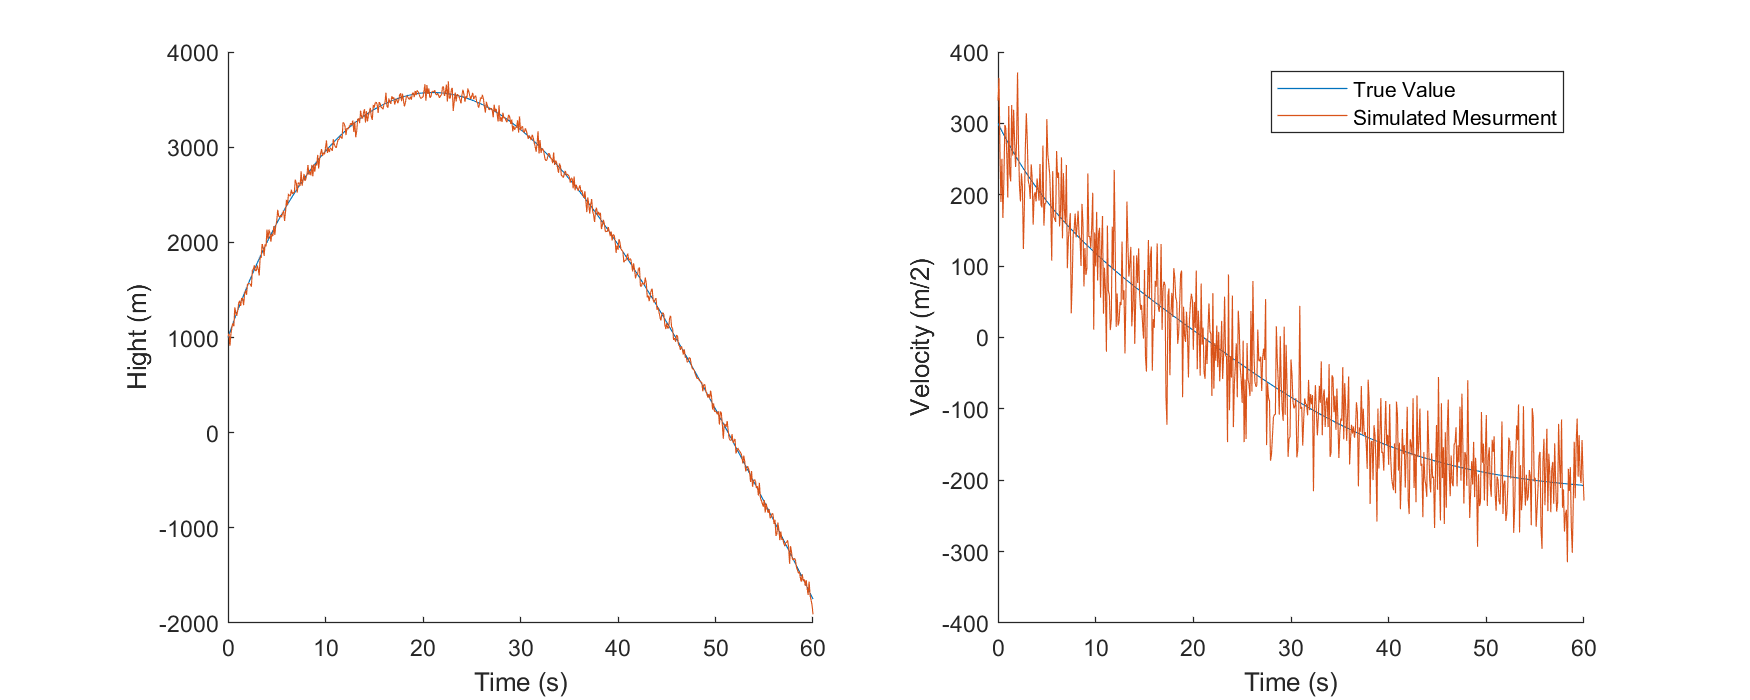

%kalman filter 2 with position and accceleration
%run simple model to generate fake positoin data for rocket
dt = 0.1;
[T, D] = altitude_model2(dt);  %dt
true_state = [D(:,1), D(:,2), D(:,3)]; %extract z position and velocity and acc data
%create normal distributed noise
sigma = 50;
noise = sigma*randn(size(true_state));
%add noise to data
noise_state = true_state + noise;

%plotting
figure(1)
clf
set(figure(1), "Position", [0 0 1000, 400])
subplot(1,2,1)
hold on
plot(T, true_state(:,1))
plot(T, noise_state(:,1))
hold off
xlabel("Time (s)")
ylabel("Hight (m)")


subplot(1,2,2)
hold on
plot(T, true_state(:,2))
plot(T, noise_state(:,2))
hold off
xlabel("Time (s)")
ylabel("Velocity (m/2)")
legend("True Value", "Simulated Mesurment")

%define some global matricies
global R Q MU;
R = [sigma^2 0  ; 0  sigma^2];  %measurement noise covarience (from the sensor: in this case sigam^2)

Error using sigma (line 82)
Not enough input arguments.

Q = [0 0 0 ; 0 0 0 ; 0 0 10 ]; %proccess noise covarience (like from assuming constnat acceleration)
%increasing Q will make filter follow measurmements more
%decrasing will make it follow internal model more
%tune this value to minmize the error

MU = -9.8;

dt = 0.1;

%set inital state and proccess covariance to first measurement
state = noise_state(1,:)';
p_cov = Q;

%make some empty arrays
kalman_state = zeros(size(noise_state));
kalman_state(1,:) = noise_state(1,:);

%loop through all mesurments and run filter
for i=2:length(noise_state)
    measurement = noise_state(i,[1,3])';
    [state, p_cov] = kalman_update2(state, p_cov, measurement, dt);
    kalman_state(i,:) = state';
end

%plot results
plot_res(T, true_state, noise_state, kalman_state)

%%==============real data with acc==================
data = readtable("altimeterfiles\flight131 austin.csv")

data = 90810×4 table
    time_acc     acc       time       alt  
    _________    ____    ________    ______
            0    6.55    0.044318    97.801
    0.0022727    6.27    0.094318    102.34
    0.0045455    5.98     0.14432     113.7
    0.0068182    5.98     0.19432    118.25
    0.0090909    6.84     0.24432    131.89
     0.011364    6.27     0.29432     138.7
     0.013636    6.27     0.34432    152.35
     0.015909    6.27     0.39432    158.03
     0.018182    6.27     0.44432     175.1
     0.020455    6.55     0.49432    184.21
     0.022727    6.27     0.54432    201.29
        0.025    6.27     0.59432     210.4
     0.027273    5.98     0.64432    230.91
     0.029545    5.98     0.69432    240.03
     0.031818    6.55     0.74432    260.56
     0.034091    6.27     0.79432    270.83

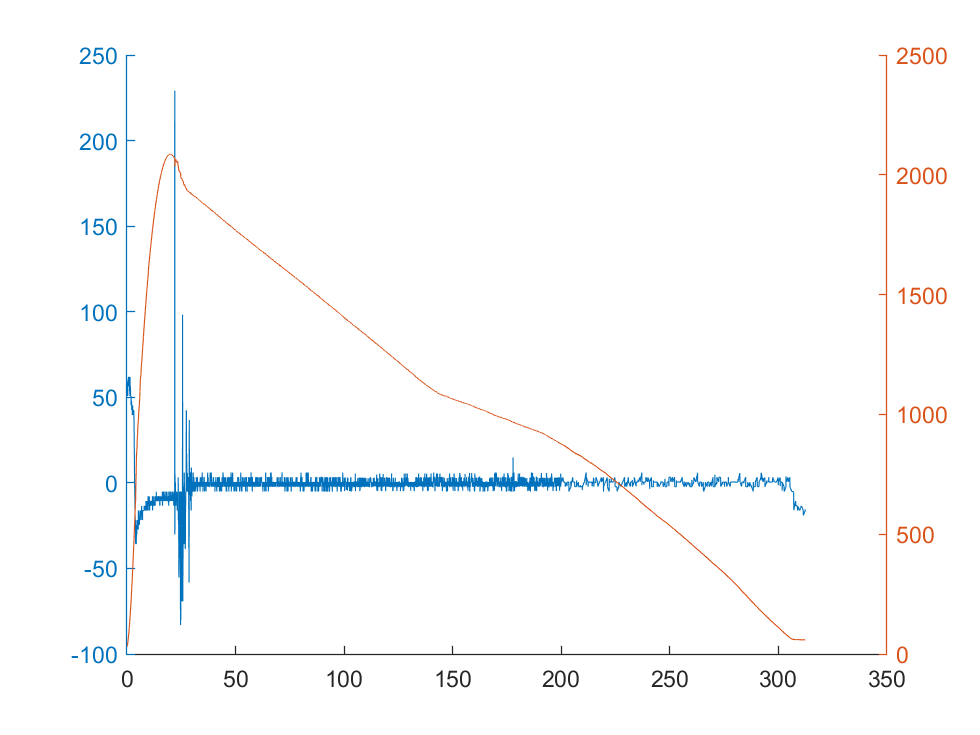

acc_us = timeseries(data.acc, data.time_acc);
alt_us = timeseries(data.alt(~isnan(data.alt)), data.time(~isnan(data.time)));
[acc_s, alt_s] = synchronize(acc_us, alt_us, "Uniform", "Interval", 0.05);
time = acc_s.Time;
alt = alt_s.Data / 3.2808;
acc = (acc_s.Data - 0.8) * 9.8;

figure()
clf
hold on
yyaxis right
plot(time, alt);
yyaxis left
plot(time, acc);

%define some global matricies
global R Q MU;
R = [100 0  ; 0  10];  %measurement noise covarience (from the sensor: in this case sigam^2)
Q = [3 0 0 ; 0 2 0 ; 0 0 1 ]; %proccess noise covarience (like from assuming constnat acceleration)
%increasing Q will make filter follow measurmements more
%decrasing will make it follow internal model more
%tune this value to minmize the error

MU = -9.8;
app = false;
app_time = [];

%set inital state and proccess covariance to first measurement
state = [alt(1); 0 ; acc(1)]

state =    29.8102
         0
   53.5571


p_cov = Q;

%make some empty arrays
kalman_state = zeros(length(time), 3);
kalman_state(1,:) = state(1,:);

%loop through all mesurments and run filter
for i=2:2
    dt = time(i) - time(i-1)
    
    measurement = [alt(i); acc(i)]
    [state, p_cov] = kalman_update2(state, p_cov, measurement, dt);
    
    
    
    if mod(i, 100) == 0
        %p_cov
    end
    kalman_state(i,:) = state';
    
    if(state(1) < kalman_state(i-1,1) && app == false)
        app_time(end+1) = data.time(i);
        app = true;
    end
end

dt = 0.0500

measurement =    31.1948
   56.3991


predicted_state =    29.8771
    2.6779
   53.5571


predicted_p_cov =     6.0050    0.1001    0.0013
    0.1001    4.0025    0.0500
    0.0013    0.0500    2.0000


kalman_gain =     0.0566    0.0001
    0.0009    0.0042
    0.0000    0.1667


state =    29.9521
    2.6909
   54.0308


p_cov =     5.6648    0.0944    0.0010
    0.0944    4.0022    0.0417
    0.0010    0.0417    1.6667


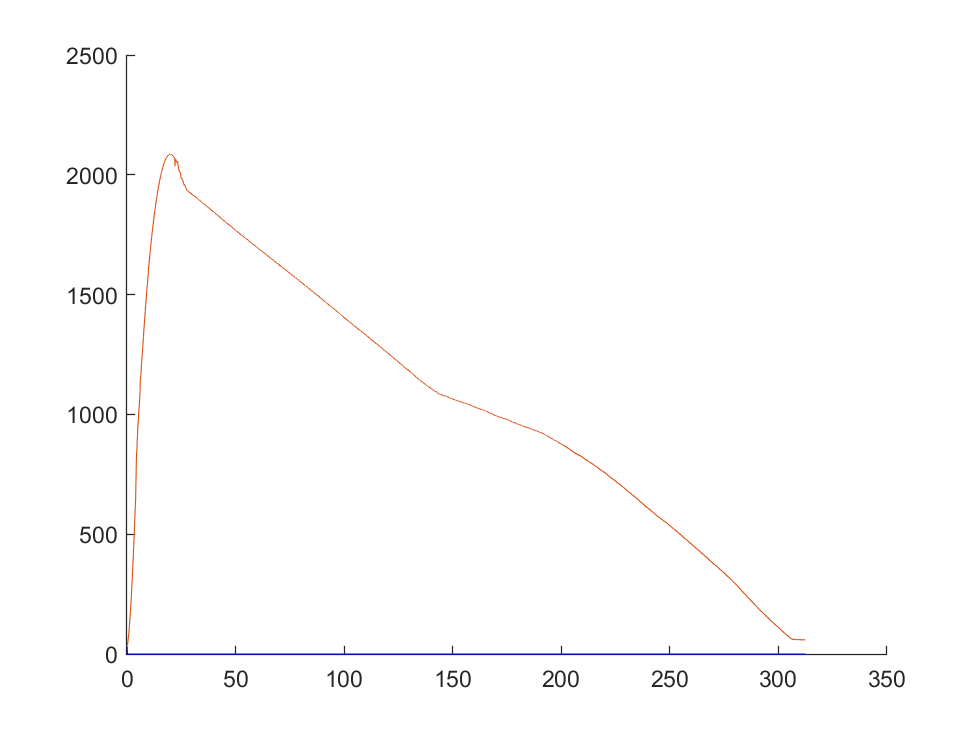

%plot results
figure()
clf
hold on
plot(time, kalman_state(:,1), 'b')
plot(time, alt)

xline(app_time)

Error using xline (line 35)
Value must be nonempty.

hold off

figure()
clf
plot(time, kalman_state(:,2))


data = 90810×4 table
    time_acc     acc       time       alt  
    _________    ____    ________    ______
            0    6.55    0.044318    97.801
    0.0022727    6.27    0.094318    102.34
    0.0045455    5.98     0.14432     113.7
    0.0068182    5.98     0.19432    118.25
    0.0090909    6.84     0.24432    131.89
     0.011364    6.27     0.29432     138.7
     0.013636    6.27     0.34432    152.35
     0.015909    6.27     0.39432    158.03
     0.018182    6.27     0.44432     175.1
     0.020455    6.55     0.49432    184.21
     0.022727    6.27     0.54432    201.29
        0.025    6.27     0.59432     210.4
     0.027273    5.98     0.64432    230.91
     0.029545    5.98     0.69432    240.03
     0.031818    6.55     0.74432    260.56
     0.034091    6.27     0.79432    270.83